cd FlashVsNoFlash/Microsoft/

f_name = "carpet_00_flash.tif";
a_name = "carpet_01_noflash.tif";

% Reading non-linear images
A = imread(a_name);
F = imread(f_name);
A = double(A);
F = double(F);
A = A/255;
F = F/255;
% Slicing image to focus on main part and reduce size to 1000x1400 for easy
% computation
A = A(501:1500, 801:2200, :);
F = F(501:1500, 801:2200, :);

% Denoising
A_Base = bilateralFilter(A,8,3);
A_NR = jointBilateralFilter(A,F,3,8);

% Detail transfer
epsilon = 0.02;
F_Base = bilateralFilter(F,8,3);
F_Detail = (F + epsilon) ./ (F_Base + epsilon);

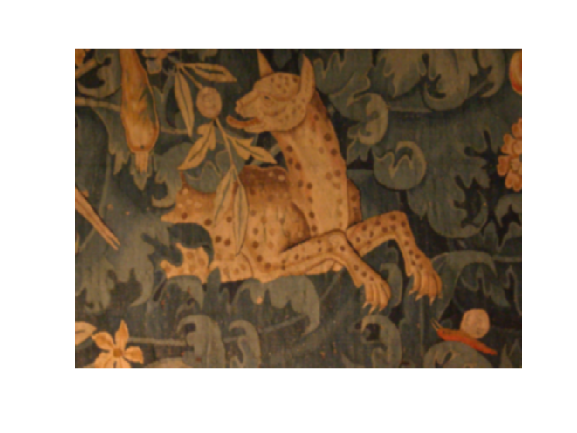

% Plotting figures
figure();imshow(A_NR);

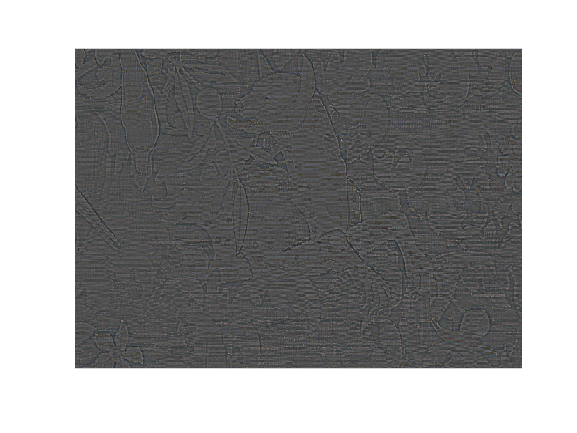

figure();imshow(F_Detail/max(F_Detail,[],"all"));

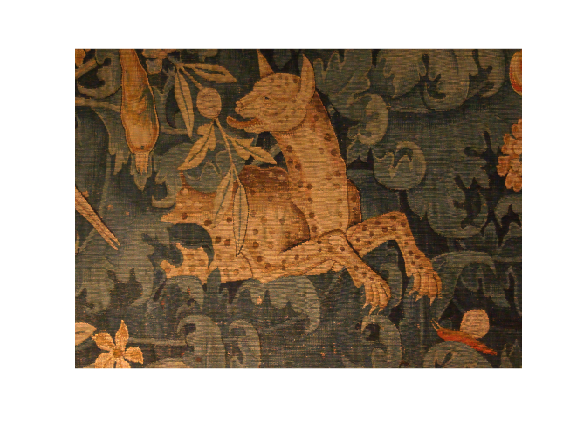

figure(); imshow(A_NR .* F_Detail);

% Mask business
A_ycbcr = rgb2ycbcr(A);
A_int = A_ycbcr(:,:,1);
F_ycbcr = rgb2ycbcr(F);
F_int = F_ycbcr(:,:,1);

ISOF = imfinfo(f_name).DigitalCamera.ISOSpeedRatings;
ISOA = imfinfo(a_name).DigitalCamera.ISOSpeedRatings;
ratio = ISOF/ISOA;

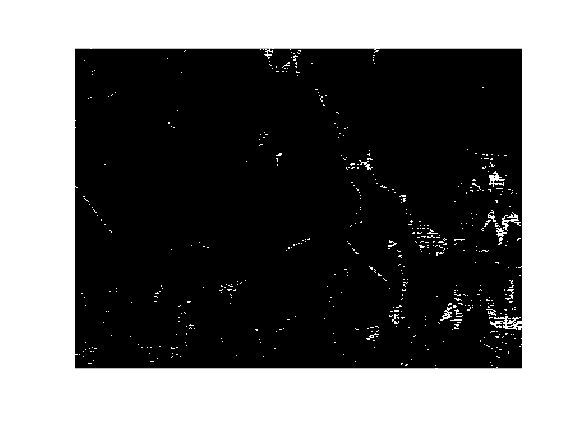

% Shadow Mask
tau = 0.12;
M_shad = (sign(tau + ratio*A_int - F_int) + 1)/2;
M_shad = imerode(M_shad, [1 1; 1 1]);
M_shad = imdilate(M_shad, [1 1; 1 1]);
figure(); imshow(M_shad);

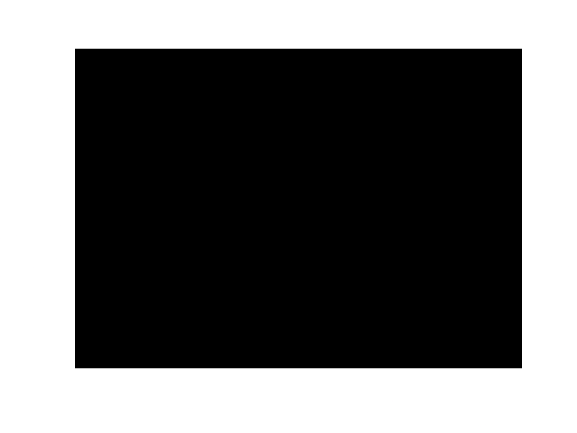

% Specularity Mask
max_val = max(F_int, [], "all");
factor = 0.95;
M_spec = (sign(F_int - factor*max_val) + 1)/2;
M_spec = imerode(M_spec, [1 1 1; 1 1 1; 1 1 1]);
M_spec = imdilate(M_spec, [1 1 1; 1 1 1; 1 1 1]);
figure(); imshow(M_spec);

% Union of masks
M = M_shad | M_spec;
figure(); imshow(M);

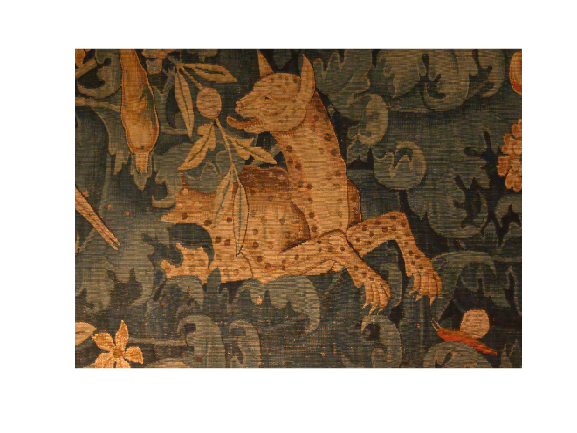

Final = (1-M).*(A_NR.*F_Detail) + M.*A_Base;
figure(); imshow(Final);